% 
clear all; close all; clc;
set_env;
%

% Data --------------------------------------------------------------
% Constants
eps_0 = 8.85e-12; 			% F/m , permittivity of vacuum

% Geometry
% tp_0 = 25e-6; 				% m   , initial thickness of polymer layer
% l_0 = 50e-3 / 2; 			% m   , initial length of polymer layer

% Acrylic dielectric
% mu_DE = 20..50; 				% -   		, Shear modulus
% lambda_DE = 7..9; 			% -   		, Max stretch
% epsilon_p = 4..4.5 * eps_0;	% F/m 		, permittivity of poymeric layer
% EBD_p = 70..120; 			    % kV / mm   , Breakdown field
% nu = 0.3; 					%  -  , Poisson's ratio of polymer

% Fluid (seawater)
% epsilon_f = 80 * eps_0; 		% F/m , permittivity of fluid (seawater)
% EBD_f =                       % kV / mm   , Breakdown field

% Operational limits -------------------------------------------------
% VBD = EBD_f * [h_f + epsilon_f / epsilon_p * (x - h_f)];
% h_f is the "thickness" of the fluid layer	 where the term in [] is minimum

% epsilon_i = lambda_DE - 1; 	% - , Max strain

% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y epsilon_p epsilon_f EBD_p EBD_f positive

% Geometry of the capacitor
syms x l_0 w tp_0 xi positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms Uel(x) V F(x,V) C(x)

% Strains: eps1 along the polymer, eps3 thickness strain of the polymer
syms epsilon_1(x) epsilon_3(x) 

% assume(nu > 0 & 'reals')
% assume(Y > 0 & 'real')
% assume(epsilon_p > 0 & 'real')
% assume(epsilon_f > 0 & 'real')
% assume(x > 0 & 'real')
% 
% assume(w > 0 & 'real')
% assume(tp_0 > 0 & 'real')
% assume(xi > 0 & 'real')
% 
% assume(l_0 > 0)
% assumeAlso(l_0 >= xi)
% assumeAlso(l_0, 'real')
% 
% assume(EBD_p, 'real')
% assume(EBD_f, 'real')


% Equations ---------------------------------------------------------
% epsilon_1(x) = sqrt(1 + x^2 / (4 * l_0^2)) - 1
% epsilon_3(x) = epsilon_1(x) * nu / (nu - 1)

l(x) = l_0 * (1 + epsilon_1(x));
t_p(x) = tp_0 * (1 + epsilon_3(x));
t_f(x) = (x / 2 - 2 * t_p) * (l_0 - xi) / l_0; 
A = l * w;
dA = w * (1 + epsilon_1(x)) ; % * dxsi

% Range limit
x_max = rhs(isolate(subsstrain(epsilon_1(x)) == 0.05, x))

$$x\_max = \frac{\sqrt{41}\,l_{0}}{10}$$


% Polymer infinitesimal capacitance
dCp = dA * epsilon_p / t_p

$$dCp(x) = \frac{\epsilon_{p}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}$$

% Fluid infinitesimal capacitance
dCf = dA * epsilon_f / t_f

$$dCf(x) = \frac{\epsilon_{f}\,l_{0}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}{\left(\frac{x}{2}-2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(l_{0}-\xi \right)}$$


% Total infinitesimal capacitance
dC = ((2 / dCp) + (2 / dCf))^(-1)

$$dC(x) = \frac{1}{\frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{\epsilon_{p}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}+\frac{2\,\left(\frac{x}{2}-2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(l_{0}-\xi \right)}{\epsilon_{f}\,l_{0}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}}$$

% Total capacitance +++++++++++++++++++++++++++++++++++++++++++++++++
C(x) = int(dC, xi)

$$C(x) = \frac{\epsilon_{f}\,l_{0}\,w\,\log\left(\epsilon_{p}\,\left(l_{0}-\xi \right)\,\left(4\,{\mathrm{tp}}_{0}-x+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{4\,{\mathrm{tp}}_{0}-x+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)}$$

C(x) = simplify(subs(C(x), xi, l_0) - subs(C(x), xi, 0))

$$C(x) = \frac{\epsilon_{f}\,l_{0}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)\,\left(\log\left(-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)-\log\left(\epsilon_{p}\,l_{0}\,\left(4\,{\mathrm{tp}}_{0}-x+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\right)}{4\,{\mathrm{tp}}_{0}-x+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)}$$

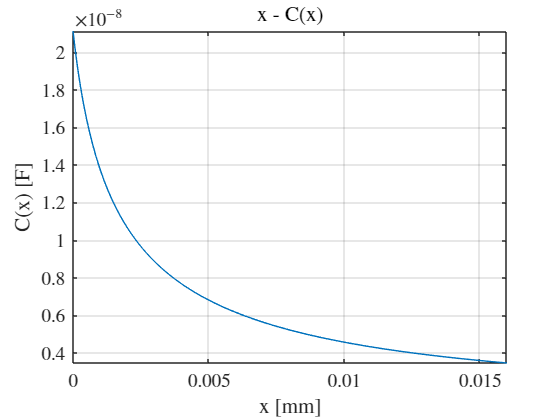

% Plot x - C(x)
% !!!!!!!!!!!!!!!!!!!!!!!!!! C(x) cresce dopo 0.1?
% fplot(x, subsdata(C(x), 'all'))
fplot(x, subsdata(C(x), 'all'), [0, subsdata(x_max)])
title("x - C(x)")
xlabel("x [mm]")
ylabel("C(x) [F]")

% Force
Uel(x) = 

Vmax(x) = A / C * min(epsilon_p * EBD_p, epsilon_f * EBD_f)

$$Vmax(x) = \frac{\left(4\,{\mathrm{tp}}_{0}-x+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)\,\min\left(\left[{\mathrm{EBD}}_{f}\,\epsilon_{f},{\mathrm{EBD}}_{p}\,\epsilon_{p}\right],\left[\right],2,\text{"omitnan"},{\mathrm{EBD}}_{f}\notin \mathbb{R}\vee {\mathrm{EBD}}_{p}\notin \mathbb{R}\vee \epsilon_{f}\notin \mathbb{R}\vee \epsilon_{p}\notin \mathbb{R}\right)}{\epsilon_{f}\,\left(\log\left(-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)-\log\left(\epsilon_{p}\,l_{0}\,\left(4\,{\mathrm{tp}}_{0}-x+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\right)}$$

subsdata(Vmax(x), 'all')

$$ans = -\frac{9\,\left(x+\frac{3\,\sqrt{400\,x^{2}+1}}{70000}-\frac{1}{7000}\right)}{160000\,\left(\log\left(\frac{1027103376344589\,\sqrt{400\,x^{2}+1}}{2707993835936769351341834240000}-\frac{342367792114863}{270799383593676935134183424000}\right)-\log\left(\frac{72924339720465819\,\sqrt{400\,x^{2}+1}}{216639506874941548107346739200000}-\frac{3081310129033767\,x}{3094850098213450687247810560}-\frac{24308113240155273}{21663950687494154810734673920000}\right)\right)}$$

Cmin = subs(C, x, 0)

$$Cmin(x) = -\frac{\epsilon_{f}\,l_{0}\,w\,\left(\log\left(\epsilon_{p}\,l_{0}\,\left(4\,{\mathrm{tp}}_{0}+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(0\right)\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(0\right)+1\right)\right)-\log\left(-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(0\right)+1\right)\right)\right)\,\left(\epsilon_{1}\left(0\right)+1\right)}{4\,{\mathrm{tp}}_{0}+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(0\right)}$$

Cmax = subs(C, x, subsdata(x_max))

$$Cmax(x) = -\frac{\epsilon_{f}\,l_{0}\,w\,\left(\log\left(\epsilon_{p}\,l_{0}\,\left(4\,{\mathrm{tp}}_{0}+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(\frac{4613937268753531}{288230376151711744}\right)-\frac{4613937268753531}{288230376151711744}\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(\frac{4613937268753531}{288230376151711744}\right)+1\right)\right)-\log\left(-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(\frac{4613937268753531}{288230376151711744}\right)+1\right)\right)\right)\,\left(\epsilon_{1}\left(\frac{4613937268753531}{288230376151711744}\right)+1\right)}{4\,{\mathrm{tp}}_{0}+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(\frac{4613937268753531}{288230376151711744}\right)-\frac{4613937268753531}{288230376151711744}}$$

x_vec = linspace(0, subsdata(x_max), 20)

x_vec =          0    0.0008    0.0017    0.0025    0.0034    0.0042    0.0051    0.0059    0.0067    0.0076    0.0084    0.0093    0.0101    0.0110    0.0118    0.0126    0.0135    0.0143    0.0152    0.0160


% % V-Q relation ++++++++++++++++++++++++++++++++++++++++++++++++++++++
% V = Q / C(x);
% 
% % Force +++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% F(x,V) = diff(Uel(x), x) - V^2 / 2 * diff(C(x), x);
% 
% epsilon_f